clear all
close all
clc

global A
global B
global control
% (J)     moment of inertia of the rotor     0.01 kg.m^2
% (b)     motor viscous friction constant    0.1 N.m.s
% (Ke)    electromotive force constant       0.01 V/rad/sec
% (Kt)    motor torque constant              0.01 N.m/Amp
% (R)     electric resistance                1 Ohm
% (L)     electric inductance                0.5 H

J = 0.01;
b = 0.1;
Ke = 0.01;
Kt = 0.01;
R = 1;
L = 0.5;

A = [-b/J Kt/J; -Ke/L -R/L];
B = [0; 1/L];
C = [1 0];



dt = 0.02

dt = 0.0200

k = 15

k = 15

x0 = [14.0317; 135.5719]

x0 =    14.0317
  135.5719



[Ad, Bd] = LTI_translation(A,B,dt);
initial_set_lo = x0;
initial_set_up = x0;
errorbound = [0.3; 100];
target_set_lo = [4;0] - errorbound

target_set_lo =     3.7000
 -100.0000


target_set_up = [4;0] + errorbound

target_set_up =     4.3000
  100.0000


utemp = recovery_control(Ad, Bd, k, initial_set_lo, initial_set_up, target_set_lo, target_set_up);

Optimal solution found.



result =    14.0317
  135.5719
   13.8401
  124.3690
   13.4843
  113.6055
   13.0018
  103.2642
   12.4232
   93.3285


inputs = utemp((length(utemp)-k+1):end);

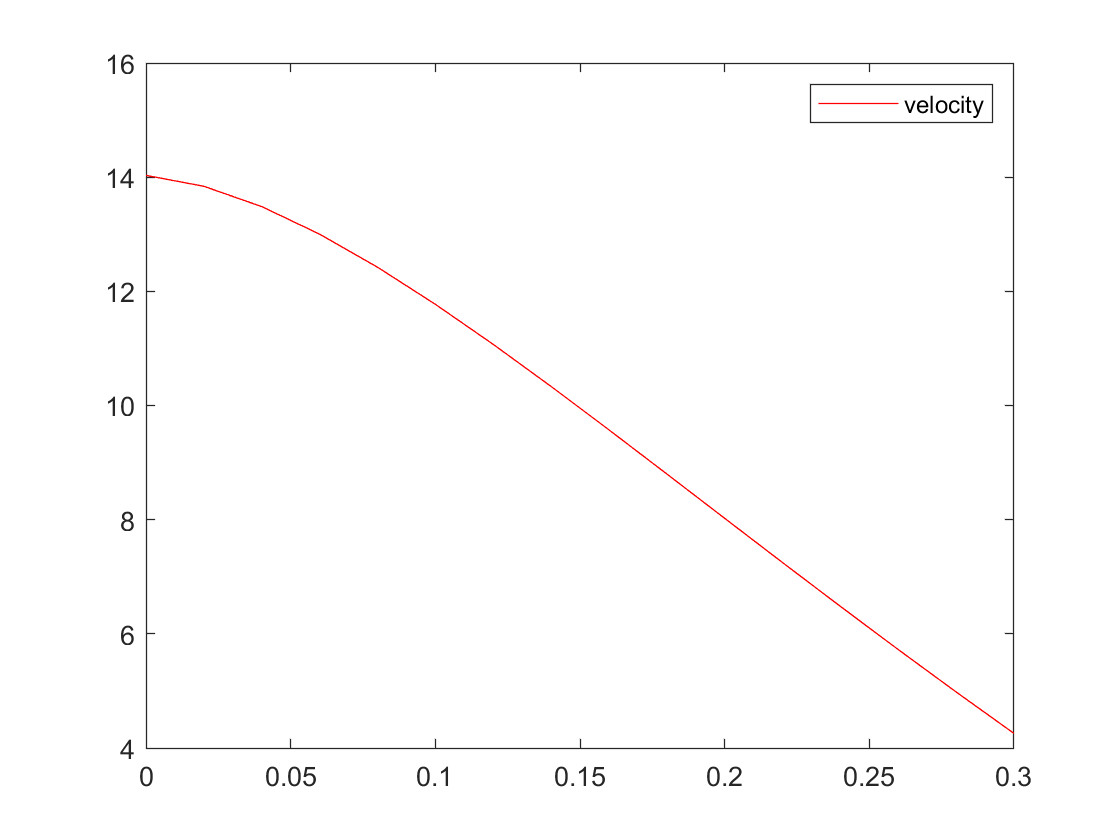

result = x0';
x = x0;
t_span = 0:dt:dt*k;

for i=1:k
   control = inputs(i,1);
   [T y] = ode45(@dynamics, [0 dt], x);
   result = [result; y(end,:)];
   x = y(end,:)';
end

plot(t_span,result(:,1),'r')
legend('velocity')

function dxdt = dynamics(t, x)

global A;
global B;
global control;

dxdt = A*x + B*control;

end